# ______________Computational Electromagnetics 

## _______________________________ Hw6-Q2

______________________Mohammadreza Arani         :::::::::::::         810100511

 __________________________________________1401/09/28     

clear; clc; close all;

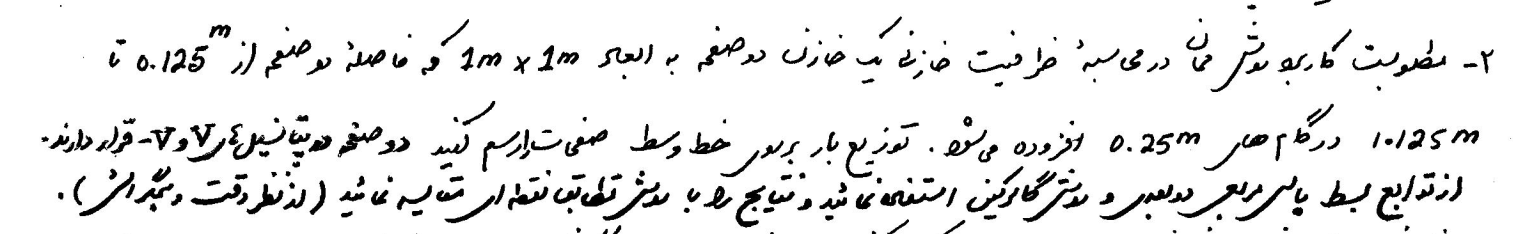

a = 1/2;

N = 9;

b = a/sqrt(N) ;


eps0 = 8.854*1e-12  ;  % F/m

**Epsilon Naught** is synonymous to the permittivity of free space or absolute  permittivity or electric constant, represented by the Greek alphabet ε0. The Epsilon Naught value is constant at any part of the universe.


delta_X = 2*b;
delta_Y = 2*b;

%syms m n 
% Self Terms:
% Find_Cordx(m)  =   mod(m,sqrt(N)+1)*delta_X  ;
% Find_Cordy(m)  =   (floor(m/sqrt(N+1)+1)*1 -  1/2)*delta_Y ;


 
N = 9;

D       = 0.125: 0.25 : 1.125 ; 
Sweep_N = [ 9 , 16 , 25 , 36 , 49 , 64  , 81 , 100];

C       = zeros( length(D) , length(Sweep_N));
C_plate = zeros( length(D),1);

A  = (2*a)^2;

Alpha_t =cell(1,length(D)) ;

for i=1:length(D)
    for j=1:length(Sweep_N)
        
        [C(i,j) , Alpha_t{i}] = Find_C(D(i) , Sweep_N(j),a );

    end
    C_plate(i,1) =  eps0*A/D(i);

end


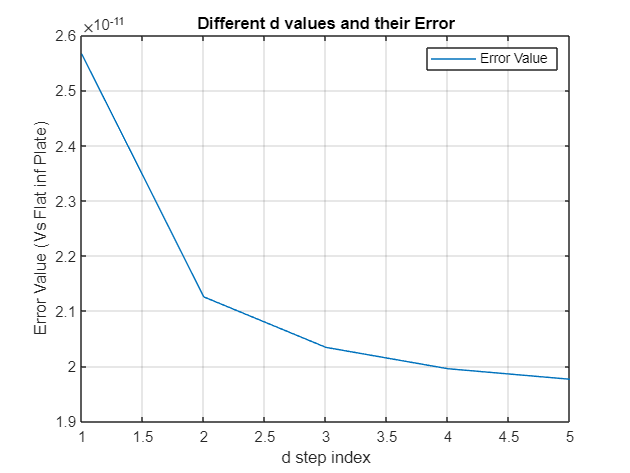



% Compare:
rep_C_Plate = repmat(C_plate , 1,length(Sweep_N));
Error  =   sqrt ( abs( rep_C_Plate  - C  ).^2  )  ;

figure(1)
plot(1:length(D) , Error(:,end))
grid on
legend("Error Value")
title("Different d values and their Error")
xlabel("d step index")
ylabel("Error Value (Vs Flat inf Plate)")

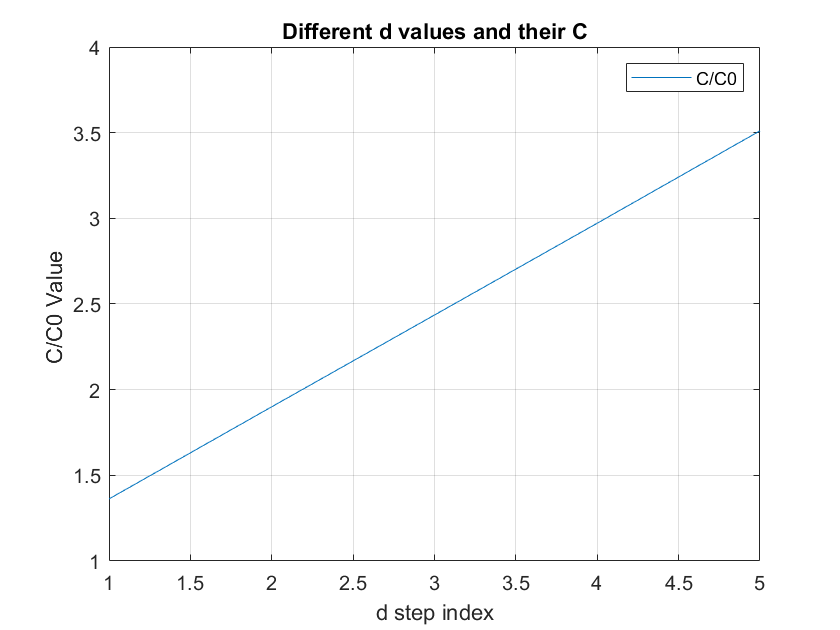


figure(2)
plot(1:length(D) , C(:,end)./C_plate)
grid on
legend("C/C0")
title("Different d values and their C")
xlabel("d step index")
ylabel("C/C0 Value ")

It is obvious and crystal clear that with increase in d (gap between 2 plates, the C/C0 value has became larger meaning **increase** in **fringing** **effect**)!!!!

## Plot the Q over the middle Line of the Plates:

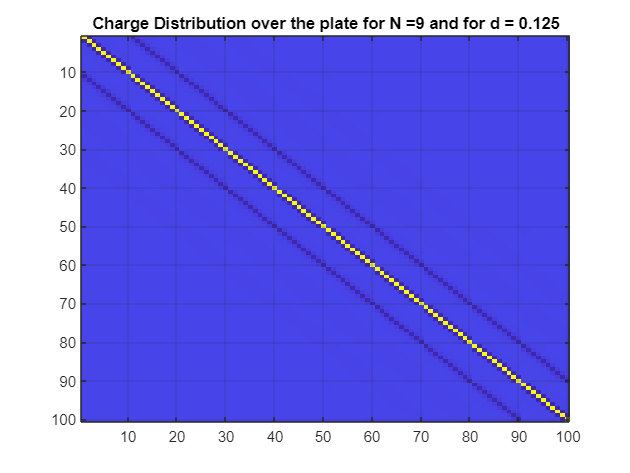



delta_Sn = (2*b)^2;


Q_T = sum( Alpha_t{1} , 'all' ) * delta_Sn; % Total Q

Charge_Distribution = Alpha_t{1};

figure(4)
imagesc(Charge_Distribution)
title("Charge Distribution over the plate for N =" + num2str(Sweep_N(1))+ " and for d = "+num2str(D(1)))
grid on

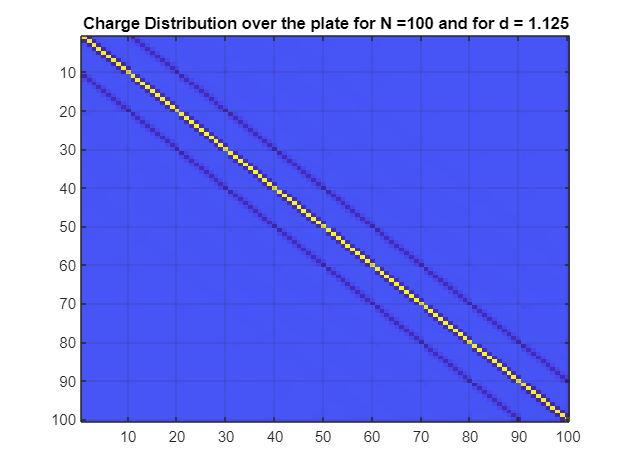


Charge_Distribution_end = Alpha_t{end};

figure(5)
imagesc(Charge_Distribution_end)
title("Charge Distribution over the plate for N =" + num2str(Sweep_N(end))+ " and for d = "+num2str(D(end)))
grid on

function   X_pos = Find_Cordx(m , N )

    if(m > sqrt(N) )
        Rem =  m - sqrt(N);
        X_pos = Find_Cordx(Rem , N);
    else
        X_pos  = ( m - 1/2);
    end
end

function   Y_pos = Find_Cordy(m , N )

     Y_pos =floor(m/sqrt(N+1)+1)*1 -  1/2;
end

function  R  = R_finder(m,n,delta_X,delta_Y,N)

R =               abs(  delta_X*Find_Cordx(m , N ) - delta_X*Find_Cordx(n , N ) )^2  + ...
                  abs(  delta_Y*Find_Cordy(m , N ) - delta_Y*Find_Cordy(n , N ) )^2  ;
end

function lmn =  lmn_tt(m, n , delta_Sn , delta_X ,  delta_Y , N )
    eps0 = 8.854*1e-12  ;  % F/m

    if(m==n)
        lmn = (sqrt(delta_Sn)/eps0)*0.2806;
    else
        lmn =  delta_Sn/(4*pi*eps0*sqrt( R_finder(m,n,delta_X,delta_Y,N))  ) ;
    end
   
end



function lmn =  lmn_tb(m, n , delta_Sn , delta_X ,  delta_Y , N , d)
    eps0 = 8.854*1e-12  ;  % F/m
    aeq  = sqrt(delta_Sn/pi)  ;

    if(m==n)
        lmn =  1/(2*eps0) * (sqrt(aeq^2+d^2) - d ) ;
    else
        lmn =  delta_Sn/(4*pi*eps0*  sqrt(R_finder(m,n,delta_X,delta_Y,N)+d^2)  ) ;
    end
   
end



function [C , Alpha_t] = Find_C(d, N,a )

    Lmn_tt = zeros(N,N);
    
    Lmn_tb = zeros(N,N);
    V =1;
    b = a / sqrt(N);
    delta_Sn  =  (2*b)^2 ;
    % eps0 = 8.854*1e-12  ;  % F/m
    delta_X = 2*b;
    delta_Y = 2*b;
    
    for i=1:N
        for j=1:N
            Lmn_tt(i,j)  = lmn_tt(i, j , delta_Sn , delta_X ,  delta_Y , N );
            Lmn_tb(i,j)  = lmn_tb(i, j , delta_Sn , delta_X ,  delta_Y , N , d);
        end
    end
    
    Alpha_t = inv(  Lmn_tt - Lmn_tb  ) * V;
    
    C = 1/(2*V) * sum(Alpha_t,'all')*delta_Sn;

end